parentDir = '\\uofa\users$\users0\a1798520\MATLAB\CNNs\rawTrain';
dataDir = 'data';
% helperCreateECGDirectories(ECGData,parentDir,dataDir)
% helperCreateRGBfromTF(ECGData,parentDir,dataDir)

allImages = imageDatastore(fullfile([pwd filesep 'rawTrain' filesep 'data' filesep]),...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');

% %training vs testing
rng default
[imgsTrain,imgsValidation] = splitEachLabel(allImages,0.8,'randomized');
disp(['Number of training images: ',num2str(numel(imgsTrain.Files))]);

Number of training images: 3228


disp(['Number of validation images: ',num2str(numel(imgsValidation.Files))]);

Number of validation images: 807


%testset
testingDir = '\\uofa\users$\users0\a1798520\MATLAB\CNNs\rawTest';
% helperCreateECGDirectories(ECGDataTest,testingDir,dataDir)
% helperCreateRGBfromTF(ECGDataTest,testingDir,dataDir)
testing = imageDatastore(fullfile([pwd filesep 'rawTest' filesep 'data' filesep]),...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');

sqz = squeezenet;
lgraphSqz = layerGraph(sqz);
disp(['Number of Layers: ',num2str(numel(lgraphSqz.Layers))])

Number of Layers: 68


disp(lgraphSqz.Layers(1).InputSize)

   227   227     3



lgraphSqz.Layers(end-5:end)

ans =   6×1 Layer array with layers:

     1   'drop9'                             Dropout                  50% dropout
     2   'conv10'                            Convolution              1000 1×1×512 convolutions with stride [1  1] and padding [0  0  0  0]
     3   'relu_conv10'                       ReLU                     ReLU
     4   'pool10'                            Global Average Pooling   Global average pooling
     5   'prob'                              Softmax                  softmax
     6   'ClassificationLayer_predictions'   Classification Output    crossentropyex with 'tench' and 999 other classes

tmpLayer = lgraphSqz.Layers(end-5);
newDropoutLayer = dropoutLayer(0.6,'Name','new_dropout');
lgraphSqz = replaceLayer(lgraphSqz,tmpLayer.Name,newDropoutLayer);

numClasses = numel(categories(imgsTrain.Labels));
tmpLayer = lgraphSqz.Layers(end-4);
newLearnableLayer = convolution2dLayer(1,numClasses, ...
    'Name','new_conv', ...
    'WeightLearnRateFactor',10, ...
    'BiasLearnRateFactor',10);
lgraphSqz = replaceLayer(lgraphSqz,tmpLayer.Name,newLearnableLayer);

tmpLayer = lgraphSqz.Layers(end);
newClassLayer = classificationLayer('Name','new_classoutput');
lgraphSqz = replaceLayer(lgraphSqz,tmpLayer.Name,newClassLayer);

lgraphSqz.Layers(63:68)

ans =   6×1 Layer array with layers:

     1   'new_dropout'       Dropout                  60% dropout
     2   'new_conv'          Convolution              3 1×1 convolutions with stride [1  1] and padding [0  0  0  0]
     3   'relu_conv10'       ReLU                     ReLU
     4   'pool10'            Global Average Pooling   Global average pooling
     5   'prob'              Softmax                  softmax
     6   'new_classoutput'   Classification Output    crossentropyex


augimgsTrain = augmentedImageDatastore([227 227],imgsTrain);
augimgsValidation = augmentedImageDatastore([227 227],imgsValidation);

ilr = 1e-4;
miniBatchSize = 64;
maxEpochs = 200;
valFreq = floor(numel(augimgsTrain.Files)/miniBatchSize);
opts = trainingOptions('sgdm',...
    'MiniBatchSize',miniBatchSize,...
    'MaxEpochs',maxEpochs,...
    'InitialLearnRate',ilr,...
    'ValidationData',augimgsValidation,...
    'ValidationFrequency',valFreq,...
    'Verbose',1,...
    'ExecutionEnvironment','gpu',...
    'Plots','training-progress');

rng default

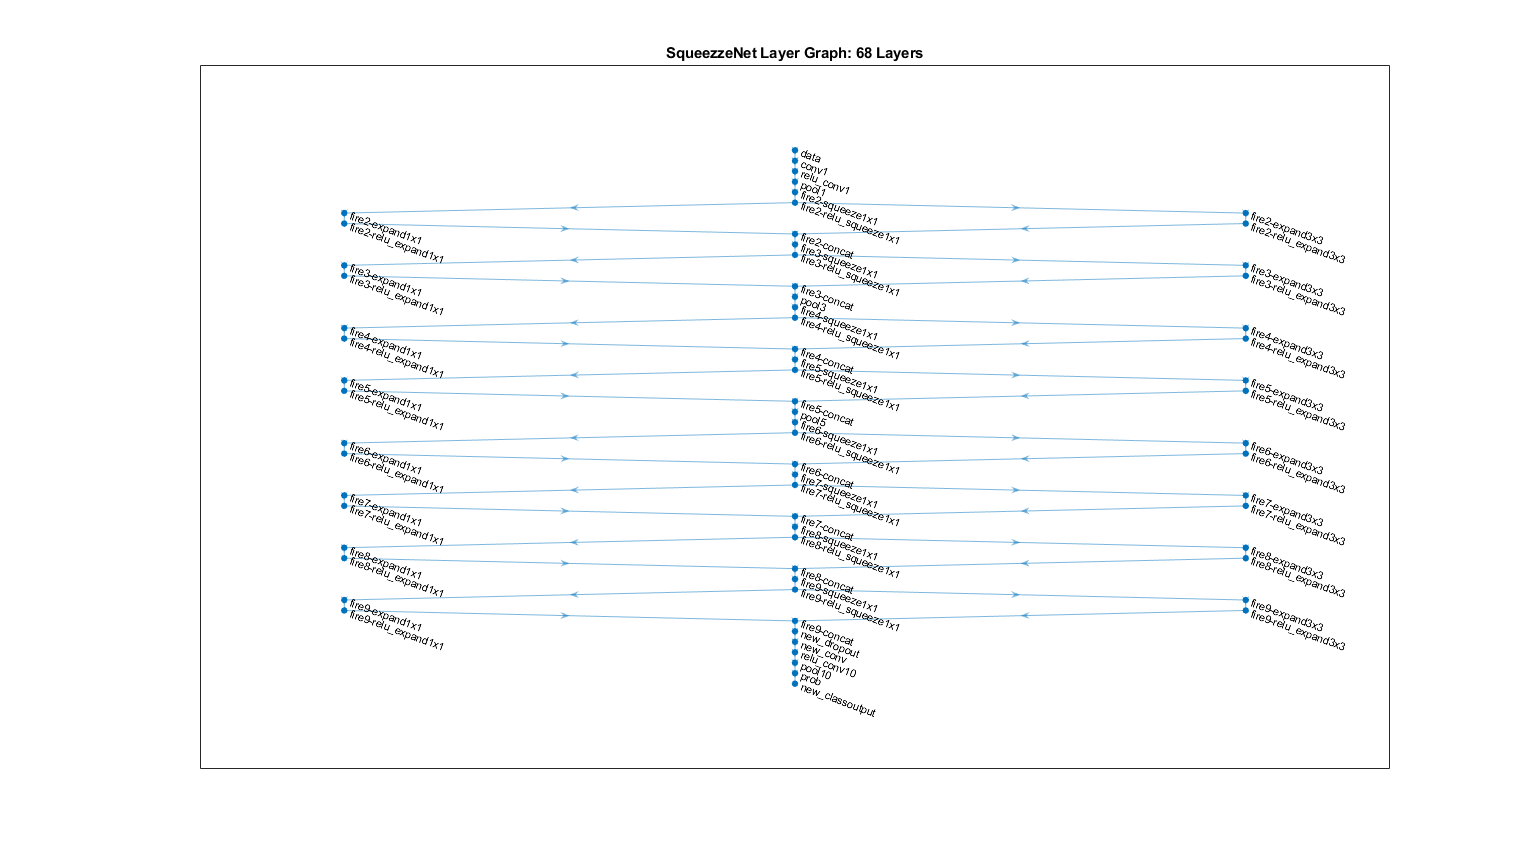


%display architecture
numberOfLayers = numel(lgraphSqz.Layers);
figure('Units','normalized','Position',[0.1 0.1 0.8 0.8]);
plot(lgraphSqz)
title(['SqueezzeNet Layer Graph: ',num2str(numberOfLayers),' Layers']);


trainedSN = trainNetwork(augimgsTrain,lgraphSqz,opts);

% [YPred,probs] = classify(trainedSN,augimgsValidation);
% disp(['SqueezeNet Accuracy: ',num2str(100*accuracy),'%'])
%performance
augimgsTesting = augmentedImageDatastore([227 227],testing);

Pred2 = classify(trainedSN, augimgsTesting);
confusionchart(testing.Labels,Pred2,'ColumnSummary','column-normalized',...
    'RowSummary','row-normalized','FontSize',20);
cfsmat2 = confusionmat(testing.Labels,Pred2);
acc2 = mean(Pred2==testing.Labels);

[p2, r2, f1_2] = predictionScoresMulti(cfsmat2);
disp(['Accuracy: ', num2str(100*acc2),'%']);
disp(['Precision: ', num2str(p2)]);
disp(['Recall: ',num2str(r2)]);
disp(['F1 score: ', num2str(f1_2)]);